# Efficient Time-Domain Cross-Correlation Sound Source Localization based on Time-Based Computing with Stochastic Construct

## 1.) Choosing the Source Localization Algorithm

Time Domain GCC-Phat based on [TIME-DOMAIN GCC-PHAT SOUND SOURCE LOCALIZATION FOR SMALL MICROPHONE ARRAYS](https://ieeexplore.ieee.org/document/6532229)

- Based on Cross Correlation

 
$$(f \star g)[n]\ \triangleq \sum_{m=-\infty}^{\infty} \overline{f[m-n]} g[m]$$


which consists of multiple dot products


$$\vec a \cdot \vec b = a_1 \, b_1 + a_2 \, b_2 + a_3 \, b_3 \ldots$$


which consists of multiplication and addition, both of which can be implemented in stochastic computing.

## 2.) Selecting the gates and represention.

- **And Gate** for multiplication

- Implementing the Addition (Summing up 128/256 Values) is more difficult

- Best to use **OR Gate** in **Unipolar** Representation 

Unipolar -> Values between [0,1]

## 3.) How to add accurate with OR gate

This example calculates the product of input*input and then sums replicas of mul N times:  $mul = input\cdot input$ followed by $\sum_1^N mul$

### Setting up Parameters

Prime_select = [32, 27]; % relative prime length of Bitstreams
input = 0.15; % range of input (between 0 and 1)

### Creating PWM Signals and Multiplying

% Creating the 
input_ones = round(input*Prime_select(1)); % Number of ones in signal
x_sc = pwmVec(input,Prime_select(1)); %generating first pwm signal
y_sc = pwmVec(input,Prime_select(2)); %generating second pwm signals
mul= scAndMul(x_sc,y_sc,Prime_select(1)*Prime_select(2)); % mulitplication result
Mul_binary = Unary2Binary(mul) % Binary represenation of input*input

Mul_binary = 0.0231

Mul_reference = myquant(input,1/Prime_select(1))*myquant(input,1/Prime_select(2))

Mul_reference = 0.0231

#### Doing Plots

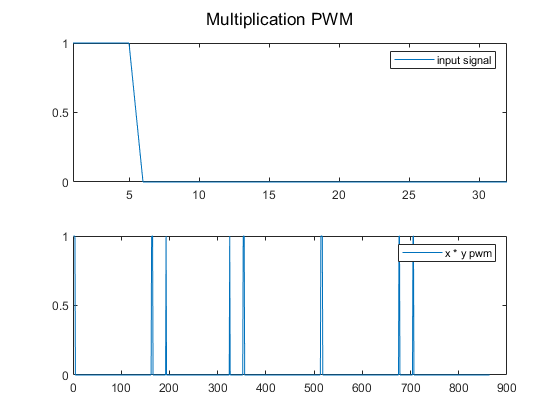

figure();
subplot(211);
plot(1:Prime_select(1),x_sc)
xlim([1,Prime_select(1)])
legend('input signal')
subplot(212);
plot(mul);
legend('x * y pwm')
sgtitle('Multiplication PWM');

## Adding Signals using Delay or Shift

Number of Summands depend on the prme-lengths and the maximum input value. For values Set above, this calculates to:

% Add multiple throu Shift
zero_len = Prime_select(2)^2+Prime_select(2)-input_ones*(2*Prime_select(2)+1)-1; %amount of guaranteed zeros between spikes
required_shift = input_ones*(Prime_select(2)+1); % Minimum Shift for zero error Add
Allowed_summands = floor(zero_len/required_shift)+1 %Amount of Summands allowed for zero error

Allowed_summands = 4

This means wie can add **Allowed_summands** using **OR-Gate **and shift of Vectors.

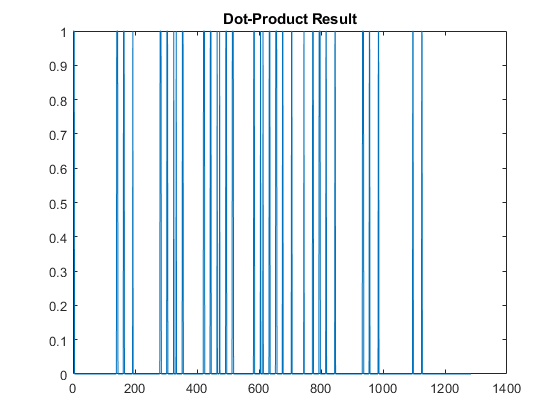

N = 4; %Number of summands

mul_mat = [repmat(mul,N,1), zeros(N,(N-1)*required_shift)]; % generating copies of mul for summing up
optional.type = 'ShiftFor'; % Implementation detail
optional.rotate = required_shift; % Implementation detail
addResult = scMultiOrAdd(mul_mat,length(mul_mat),optional); %doing the summing

figure();plot(addResult); title('Dot-Product Result')

Dot_product_binary = sum(addResult)/Prime_select(1)/Prime_select(2)

Dot_product_binary = 0.0926

Dot_product_refernce = (N)*Mul_reference

Dot_product_refernce = 0.0926

- In The Implementation instead of shifting, most likely a a rotation will be used. Cheaper to Implement. This means, that less summands are summands possible with zero error for a given maximum input and Prime_length

- Furthermore we the amount of inputs is high in cross correlation, therefor we will tolerate some error to further save ressources.

## 4) Optaining an Unary Audio Signal

By Nature, all audio Signals are oscillations around zero, therefore containing negative values. An analog circuit is required to cut negative half waves.

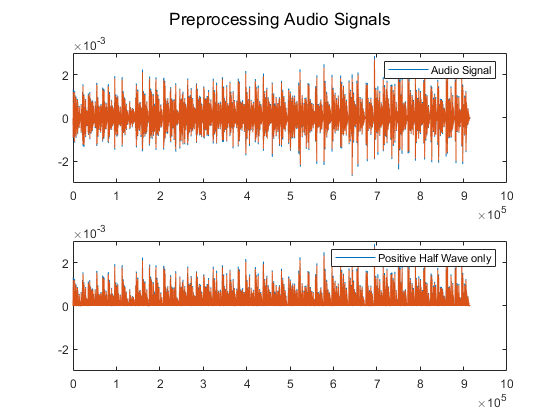

load('fs_12k.mat')
figure();
subplot(211);
plot(X);
ylim([-3*10^(-3) 3*10^(-3)])
(legend('Audio Signal'))
subplot(212);
X(X<0) = 0;
plot(X);
ylim([-3*10^(-3) 3*10^(-3)])
legend('Positive Half Wave only')
sgtitle('Preprocessing Audio Signals')

### LT Spice Model of Analog Circuit